# **1D Heat equation** - Explore the MATLAB function `pdepe`

Recall a summary of our specific **Boundary value problem** problem:

-    $\frac{\partial U}{\partial t}\;\;\;=\;\;\;\;\alpha \;\ldotp \;\frac{\partial^2 }{\partial x^2 }U$      for   $\left(0<x<1\right)$   and    $\left(t\;>\;0\right)$

- $U\left(x,t\right)$    :     Temperature     $\left\lbrack \circ K\;\right\rbrack$

- $x$             :     a  position          $\left\lbrack m\;\;\right\rbrack$

- $t$             :      a  time               $\left\lbrack \sec \;\;\right\rbrack$

- $\alpha$            :  Thermal diffusivity  $\left\lbrack \frac{m^2 }{\sec }\right\rbrack$    ***ATTENTION***:   we will use $\alpha =1$

- BCs:    $\begin{array}{l}
U\left(0,t\right)\;=0\\
U_X \left(1,t\right)=1
\end{array}$    for $\left(t\;>\;0\right)$

- ICs:    $U\left(x,0\right)=f\left(x\right)$    where   $f\left(x\right)\;\;=\;\;x\;\;\;+\;\;\;A\ldotp \sin \left(\frac{\pi \ldotp x}{2}\right)\;\;\;+\;\;\;B\ldotp \sin \left(\frac{P\ldotp \pi \ldotp x}{2}\right)$    where    $\begin{array}{l}
A=2\ldotp 2\\
B=0\ldotp 7\\
P=3\;\;\;
\end{array}$

To use the [`pdepe`](matlab:  doc pdepe) function we need our problem in the form:

- PDE:    $c\left(x,t,u,\frac{\partial u}{\partial x}\right)\ldotp \frac{\partial u}{\partial t}\;\;\;\;=\;\;\;\;x^{-m} \ldotp \frac{\partial }{\partial x}\left(x^m \ldotp f\left(x,t,u,\frac{\partial u}{\partial x}\right)\right)\;\;\;\;+\;\;\;\;\;s\left(x,t,u,\frac{\partial u}{\partial x}\right)$

- BCs:    $p\left(x,t,u\right)\;\;+\;\;q\left(x,t\right)\ldotp f\left(x,t,u,\frac{\partial u}{\partial x}\right)\;=\;0$

Specifically we need to 

- write a function that defines the values of $c,f,s$ as functions of $x,t,u,\frac{\partial u}{\partial x}$, ie:  ` function [c,f,s] = ``LOC_my_pde``(x,t,u,dudx)`

- write a function that defines the ICs  $u\left(x,t_0 \right)=f\left(x\right)$  in the form  `function u0 = ``LOC_my_ICs``(x)`

- write a function that defines the BCs in the form  ` [pl,ql,pr,qr] = ``LOC_my_BCs``(xl,xr,ur,t)`

- 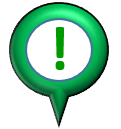**NOTE:**   We've implemented these as subfunctions at the bottom of this script

Now let's call the [`pdepe`](matlab:  web(fullfile(docroot, 'matlab/ref/pdepe.html#mw_ca773a23-ccd3-45fc-9eb0-0982f085f21d'))) function.  The pdepe function will return an array containing our solution.  The solution array has the form $U\left({\;t}_j ,{\;x}_k \;\;\right)$

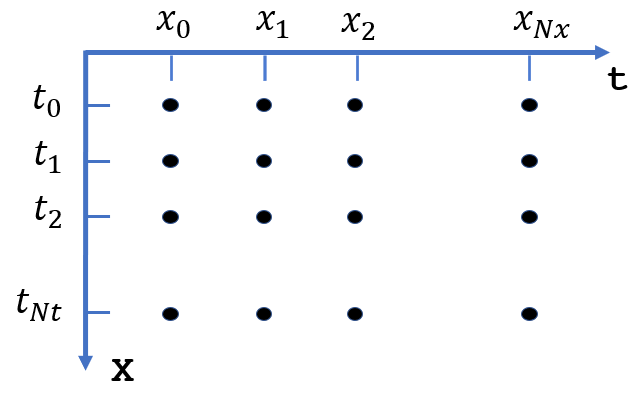

options    = odeset('RelTol',1e-6,'AbsTol',1e-6);
my_x_list  = 0:0.001:1;
my_t_list  = 0:0.001:0.084;  %0.2;

my_sol     = pdepe(0, @LOC_my_pde, @LOC_my_ICs, @LOC_my_BCs, my_x_list, my_t_list, options);

whos   my_sol    my_x_list   my_t_list

## Now visualize the solution:

- 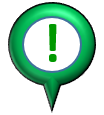 NOTE:  the slider bar represents "normalised time", i.e.: 

- $\Longrightarrow$` t_norm = 1`  , corresponds to $t=t_{\textrm{MAX}}$

- $\Longrightarrow$` t_norm = 0`  , corresponds to $t=t_{\textrm{MIN}}$

t_norm = 0.25;
LOC_slice_and_dice_for_pdepe(my_sol, my_x_list, my_t_list, t_norm)

# Local subfunctions only beyond this point

### Here's our PDE function

- PDE - our specific PDE:        $\frac{\partial \:U}{\partial t }=\frac{\partial^{\: 2\;} U}{\partial x^2 }$

- PDE - GENERAL form:        $c\left(x,t,u,\frac{\partial u}{\partial x}\right)\ldotp \frac{\partial u}{\partial t}\;\;\;\;=\;\;\;\;x^{-m} \ldotp \frac{\partial }{\partial x}\left(x^m \ldotp f\left(x,t,u,\frac{\partial u}{\partial x}\right)\right)\;\;\;\;+\;\;\;\;\;s\left(x,t,u,\frac{\partial u}{\partial x}\right)$

function [c,f,s] = LOC_my_pde(x,t,u,dudx)
    c = 1;
    f = dudx;
    s = 0;
end

### Here's our ICs

- $U\left(x,0\right)=f\left(x\right)$   where   $f\left(x\right)\;\;=\;\;x\;\;\;+\;\;\;A\ldotp \sin \left(\frac{\pi \ldotp x}{2}\right)\;\;\;+\;\;\;B\ldotp \sin \left(\frac{P\ldotp \pi \ldotp x}{2}\right)$

function u0 = LOC_my_ICs(x)
     [A,B,P] = LOC_get_ABP();

  Name            Size               Bytes  Class     Attributes

  my_sol         85x1001            680680  double              
  my_t_list       1x85                 680  double              
  my_x_list       1x1001              8008  double              



     
     u0  = x + A*sin(pi*x/2)  + B*sin(P*pi*x/2);
end

### Here's our BCs

- BCs - our specific BCs:        $\begin{array}{l}
U\left(0,t\right)\;=0\\
U_X \left(1,t\right)=1
\end{array}$    for $\left(t\;>\;0\right)$

- BCs - GENERAL form:        $p\left(x,t,u\right)\;\;+\;\;q\left(x,t\right)\ldotp f\left(x,t,u,\frac{\partial u}{\partial x}\right)\;=\;0$

Recall also, that we when we defined our PDE(see `LOC_my_pde`) we stated that:

- 
$$f\left(x,t,u,\frac{\partial u}{\partial x}\right)\;=\;\;\frac{\partial u}{\partial x}$$


So converting our specific BCs into the GENERAL form, we have:

- LEFT:          $U\left(0,t\right)\;=0\;\;\;\;\;\;\Longrightarrow \;\;\;\;\;\;U\left(0,t\right)\;\;\;\;+\;\;\;\;\;\;\;\;\;\;0\;\ldotp \frac{\;\partial u}{\partial x}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;0\;\;\;$

- RIGHT:        $U_X \left(1,t\right)=1\;\;\;\;\Longrightarrow \;\;\;\;-1\;\;\;\;\;\;\;\;\;\;\;+\;\;\;\;\;\;\;\;\;\;1\;\ldotp \;\frac{\partial u}{\partial x}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;0\;\;\;$

-                                                    
$$p\left(x,t,u\right)\;\;\;\;+\;\;q\left(x,t\right)\ldotp f\left(x,t,u,\frac{\partial u}{\partial x}\right)\;=\;0$$


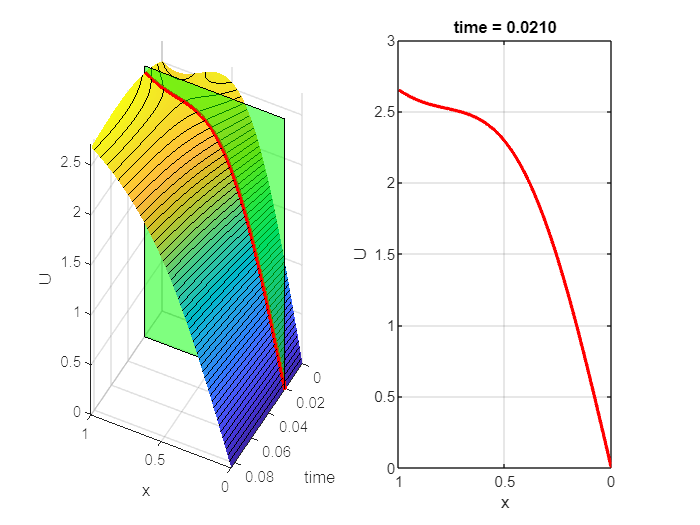

function [pl,ql,pr,qr] = LOC_my_BCs( xl,ul, xr,ur , t)
    pl = ul;

    ql = 0;
    pr = -1;
    qr = 1;
end

### Other things:

function [A,B,P] = LOC_get_ABP()
    A       = 2.2;
    B       = 0.7; %2.2; %0.7;
    P       = 3;    
end

**Slice and Dice for pdepe results:**

Recall the layout of the U solution

function LOC_slice_and_dice_for_pdepe(U, x_list, t_list, t_norm)

    kk_t   = 1 +  round(t_norm*(-1+length(t_list)));

    t_val = t_list(kk_t);   
    U_vec = U(kk_t,:);
    x_vec = x_list;
      
    % set up figure and the 2 axes
    figure;
    hax(1) = subplot(1,2,1);
    hax(2) = subplot(1,2,2);
   
    % plot the U vs X slice
    plot(hax(2), x_vec, U_vec, '-r', 'LineWidth', 2);
        grid(hax(2), 'on');
        xlabel(hax(2),'x'); ylabel(hax(2),'U');
        set(hax(2), 'XDir', 'reverse');
        title("time = " + num2str(t_val, '%.4f') );
    
    % plot the 3D surface
    t = t_list;
    x = x_list;
    hAX = hax(1);
    surf(hAX, x,t, U, 'EdgeColor','none');
        xlabel(hAX,'x');
        ylabel(hAX, 'time');
        zlabel(hAX, 'U');
        %lightangle(75, 70)
        hold(hAX,'on')
    contour3(hAX, x,t, U, 50, '-k')    
       
    % plot the slice plane
    yp = [t_val, t_val, t_val, t_val ];
    xp = [x_vec(1), x_vec(end), x_vec(end), x_vec(1) ];
    zp = [0,0,max(U,[],'all'), max(U,[],'all')];
    patch(hAX, xp,yp,zp, 'g', 'FaceAlpha', 0.5);   
    y_vec = t_val*ones(size(x_vec));
    
    plot3(hAX,x_vec,y_vec,U_vec, '-r', 'LineWidth',3)
    %view(hAX,[36.66 29.04])
    view(hAX,[207.05 23.26])
end